Question 1 Part A) Implementing PCA

load 0_1_2.mat;

Centrolize X Below as Xt

CMean = mean(X,2);
ss = ones(1,300);
Xt = (X - gmultiply(ss, CMean));
Ccov = (Xt)*(Xt');

Singular Decomposition - The first 2 vectors are the largest eigenvectors

[U,S,V] = svd(Ccov);

Project 2 vectors

Ypca = U(:,1:2)' * -Xt;

Reshape and plot images

images = reshape(X,8,8,300);
plotimages(images,Ypca,0.08,0.25); 

Q1 Part B Implementing FCA

Define X1, X2 and X3 

X1 = X(:,1:100);
X2 = X(:,101:200);
X3 = X(:,201:300);
Sw = cov(X1')+cov(X2')+ cov(X3');
m1 = mean(X1,2);
m2 = mean(X2,2);
m3 = mean(X3,2);
Sb = (m1 - m2)*(m1 - m2)'+(m1 - m3)*(m1 - m3)'+(m2 - m3)*(m2 - m3)';

Find Largest Eigenvalue

Q = inv(Sw)*Sb;
[V,D] = eig(Q);
eigval=diag(D);
[sort_eigval,sort_eigval_index]=sort(eigval,'descend');
W=V(:,sort_eigval_index(1:2));

Then find y and add 2D presentation

y = W'*X;
images = reshape(X,8,8,300);
Yfca = [y; randn(1,300)];
plotimages(images,Yfca,0.005,0.2);

Q1 Part c 

Elements

C1 = Ypca(:,1:100);
C2 = Ypca(:,101:200);
C3 = Ypca(:,201:300);
C1 = C1';
C2 = C2';
C3 = C3';
C = Ypca';
n1 = 100;
n2 = 100;
n3 = 100;
N = 300; 
mu1=mean(C1);
mu2=mean(C2);
mu3=mean(C3);
mu = mean(C);
D1=C1-repmat(mu1,n1,1);
D2=C2-repmat(mu2,n2,1);
D3=C3-repmat(mu3,n3,1);
D = C - repmat(mu,N,1);
Cov1=D1'*D1;
Cov2=D2'*D2;
Cov3=D3'*D3;
Cov = D'*D;
Cov1 = 1/n1 .* Cov1;
Cov2 = 1/n2 .* Cov2;
Cov3 = 1/n3 .* Cov3;
Cov = 1/N * Cov;
invCov1=inv(Cov1);
invCov2=inv(Cov2);
invCov3=inv(Cov3);
invCov = inv(Cov);
P1=n1/N;
P2=n2/N;
P3=n3/N;

LDA 

We want to find A, B, where  ATx + B = 0, x = [x,y]

Assume Cov1 = Cov2 = Cov3 = Cov

LDAWi0 represents the bias term

LDAWi is the coefficients of the linear term

LDAW10=log(P1)-0.5*mu1*((invCov)*mu1');
LDAW1=(invCov)*mu1';

LDAW20=log(P2)-0.5*mu2*((invCov)*mu2');
LDAW2=(invCov2)*mu2';

LDAW30=log(P3)-0.5*mu3*((invCov)*mu3');
LDAW3=(invCov)*mu3';

Below is the functions

SW12 = LDAW1 - LDAW2;
SW13 = LDAW1 - LDAW3;
SW23 = LDAW2 - LDAW3;
A = [SW12';SW13';SW23']

A =     4.7368    1.2140
    0.8988    0.7053
   -3.8380   -0.5087


B = [LDAW10 - LDAW20;LDAW10 - LDAW30;LDAW20 - LDAW30]

B =    -0.0458
   -0.5915
   -0.5456


LDAS12 = @(x,y) SW12(1)* x + SW12(2)* y + B(1)==0;
LDAS13 = @(x,y) SW13(1)* x + SW13(2)* y + B(2)== 0;
LDAS23 = @(x,y) SSW23(1)* x + SW23(2)* y + B(3)== 0;

LDA = @(x,y) A * [x;y] + B

LDA = function_handle with value:
    @(x,y)A*[x;y]+B


QDA

We want to find D, F, C, where FT x +C,  x = [x;y;x^2;x*y;y^2] 

Wi0 represents the bias term

Wi is the coefficients of the linear term

WWi is the qudaratic term

W10=log(P1)-0.5*mu1*((invCov1)*mu1');
W1=(invCov1)*mu1';
WW1=-0.5 * invCov1;

W20=log(P2)-0.5*mu2*((invCov2)*mu2');
W2=(invCov2)*mu2';
WW2=-0.5 * invCov2;

W30=log(P3)-0.5*mu3*((invCov3)*mu3');
W3=(invCov3)*mu3';
WW3=-0.5 * invCov3;

SWW12 = WW1 - WW2;
SWW13 = WW1 - WW3;
SWW23 = WW2 - WW3;
QSW12 = W1 - W2;
QSW13 = W1 - W3;
QSW23 = W2 - W3;
C = [W10 - W20;W10 - W30;W20 - W30]

C =    -0.0319
   -2.4484
   -2.4165


F = [QSW12(1),QSW12(2),SWW12(1,1),SWW12(1,2)+SWW12(2,1),SWW12(2,2);
    QSW13(1),QSW13(2),SWW13(1,1),SWW13(1,2)+SWW13(2,1),SWW13(2,2);
    QSW23',SWW23(1,1),SWW23(1,2)+SWW23(2,1),SWW23(2,2)]

F =     7.5636    1.6946    0.0584    0.4560   -0.6589
    3.8912    1.6291    1.5717    0.4821    0.4353
   -3.6724   -0.0654    1.5133    0.0261    1.0942


D = [SWW12;SWW13;SWW23]

D =     0.0584    0.2280
    0.2280   -0.6589
    1.5717    0.2411
    0.2411    0.4353
    1.5133    0.0131
    0.0131    1.0942



QDA = @(x,y) F * [x;y;x^2;x*y;y^2] + C

QDA = function_handle with value:
    @(x,y)F*[x;y;x^2;x*y;y^2]+C


Question 1 Part D

LDAS12 = @(x,y) SW12(1)* x + SW12(2)* y + B(1);
LDAS13 = @(x,y) SW13(1)* x + SW13(2)* y + B(2);
LDAS23 = @(x,y) SW23(1)* x + SW23(2)* y + B(3);
QDAS12 = @(x,y) QSW12(1) * x + QSW12(2) * y + SWW12(1,1) * x^2 + (SWW12(1,2)+SWW12(2,1))*x*y + SWW12(2,2) * y^2;
QDAS13 = @(x,y) QSW13(1) * x + QSW13(2) * y + SWW13(1,1) * x^2 + (SWW13(1,2)+SWW13(2,1))*x*y + SWW13(2,2) * y^2;
QDAS23 = @(x,y) QSW23(1) * x + QSW23(2) * y + SWW23(1,1) * x^2 + (SWW23(1,2)+SWW23(2,1))*x*y + SWW23(2,2) * y^2;
plotimages(images,Ypca,0.03,0.25); 
hold on
fimplicit(LDAS12,[-2.5 2.5 -2.5 2]);
hold on 
fimplicit(LDAS13,[-2.5 2.5 -2.5 2]);
hold on 
fimplicit(LDAS23,[-2.5 2.5 -2.5 2]);
hold on
fimplicit(QDAS12,[-2.5 2.5 -2.5 2]);

hold on 
fimplicit(QDAS13,[-2.5 2.5 -2.5 2]);

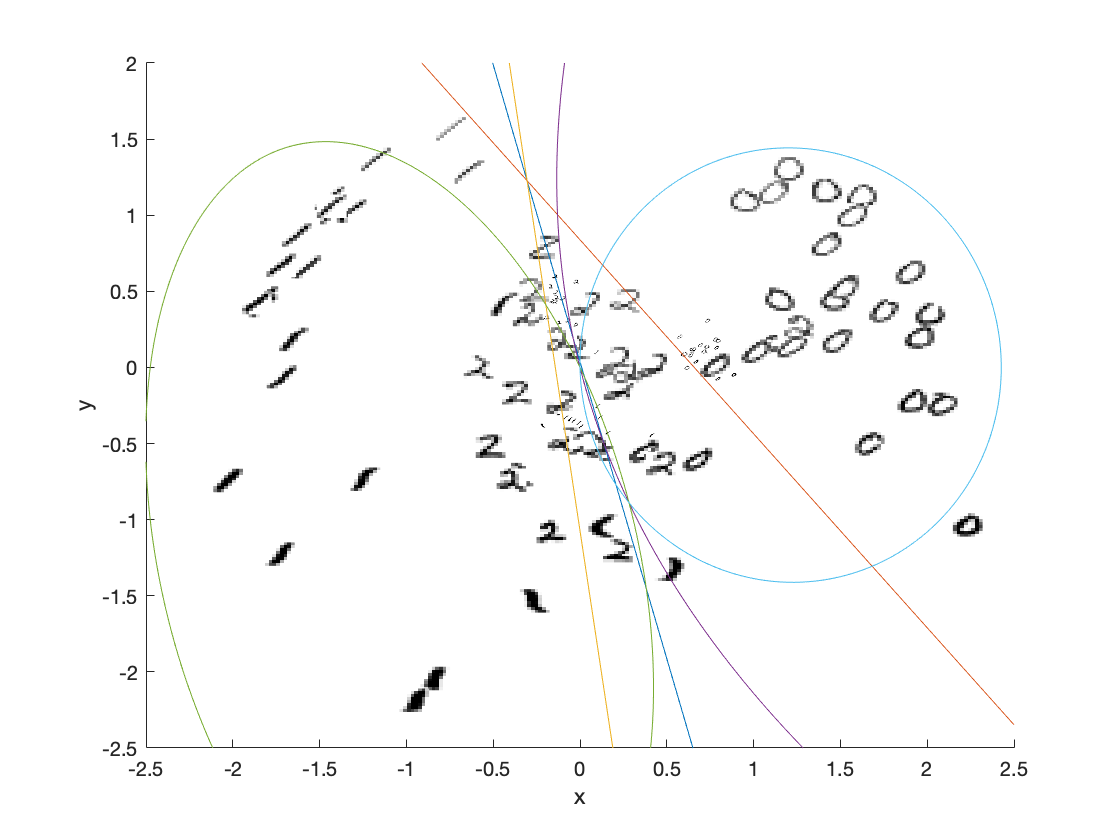

hold on 
fimplicit(QDAS23,[-2.5 2.5 -2.5 2]);

Question 1 Part e

apply LDA to Ypca

Class12 = bsxfun(LDAS12,Ypca(1,:),Ypca(2,:));
Class13 = bsxfun(LDAS13,Ypca(1,:),Ypca(2,:));
Class23 = bsxfun(LDAS23,Ypca(1,:),Ypca(2,:));
x1 = Class12(1,1:100);
countC1 = length(nonzeros(x1(x1>0)));
x2 = Class23(1,101:200);
countC2 = length(nonzeros(x2(x2>0)));
x3 = -Class13(1,201:300);
countC3 = length(nonzeros(x3(x3>0)));
Correct = countC1 +countC2+countC3;
Error_rate = 1- Correct / 300

Error_rate = 0.0600

The Error Rate is 6% using LDA 

Question 1 Part f

Answer: Yes. We can implement QDA based on the Euclidian distance between points and the mean of each class. The output will be identical to the QDA I computed in c. It is because by transformation of S_k^(-0.5) *  (U_k)T, we can achieve the identical matrix as its sigma_k matrix. Then we can apply the Euclidian distance between points and the mean of each class.